# Modelling and Simulation in Structural Mechanics

In many cases, numerical models of complex systems need to be large in size to produce acceptable results. This results in a high memory consumption as well as long computation times, which can be infeasible even for modern machines. In the following exercises, some methods to reduce the size of numerical systems are presented. Smaller systems can be evaluated with less computational costs and are therefore required in many application cases, such as optimization or continuous monitoring of dynamic systems.

In order to run the following examples, the `bm_mfem` package must be added to your MATLAB path.

## Static condensation

First, a classic method to reduce the size of the stiffness matrix for static FEM analyses, known as *Static Condensation* or *Guyan Reduction*, is presented.

We first create a model of a plate, clamped at two oppositing ends and choose a relatively fine discretization in order to see the effect of the reduction. We will use Reissner-Mindling plate elements, as we only consider loading orthogonal to the plate. The classic Static Condensation is, as the name suggests, only valid for static problems. We are therefore only using the model's stiffness matrix.

clear; close all;

nx = 40;        % elements in x
ny = 8;         % elements in y
l = 0.3;        % length
w = 0.025;      % width
h = 0.002;      % height

[model, x0, xend] = createRectangularPlate(l,w,nx,ny,...
    'elementType','ReissnerMindlinElement3d4n');
model.getAllNodes.addDof({'DISPLACEMENT_Z', 'ROTATION_X', 'ROTATION_Y'});

x0.fixAllDofs();        % clamped at x=0.0
xend.fixAllDofs();      % clamped at x=0.3

model.getAllElements.setPropertyValue('YOUNGS_MODULUS',2.1e11);
model.getAllElements.setPropertyValue('POISSON_RATIO',.3);
model.getAllElements.setPropertyValue('THICKNESS',h);
model.getAllElements.setPropertyValue('DENSITY',7860);
model.getAllElements.setPropertyValue('NUMBER_GAUSS_POINT',2);
model.getAllElements.setPropertyValue('SHEAR_CORRECTION_FACTOR',5/6);

[~,K] = SimpleAssembler.assembleGlobalStiffnessMatrix(model);

We now apply some loads as forces in z-direction (orthogonal to the plate) and retrieve the force vector. Now we have all inputs we need to perform the Static Condensation.

id_load_1 = fix(length(model.getAllNodes())/3.7)+1;
model.getNode(id_load_1).setDofLoad('DISPLACEMENT_Z',-1);
id_load_2 = fix(length(model.getAllNodes())/1.4)+1;
model.getNode(id_load_2).setDofLoad('DISPLACEMENT_Z',-3);
id_load_3 = fix(length(model.getAllNodes())/2.1)+1;
model.getNode(id_load_3).setDofLoad('DISPLACEMENT_Z',3);

[~,f] = SimpleAssembler.applyExternalForces(model);

The Static Condensation computes the solution of the system only at a defined set of locations, called active dofs in the following. We choose the loaded dofs as active dofs and can now reorder the stiffness matrix and force vector according to


$$K_G= \left[\matrix{ K_{aa} & K_{ai} \cr K_{ia} &K_{ii}} \right],$$


where $K_{aa}$ denotes the stiffness at the active dofs, $K_{ii}$ the stiffness at the inactive dofs, and $K_{ia},K_{ai}$ the stiffness at the interface between active and inactive dofs. Of course also the force vector has to be sorted accordingly:


$$f_G= \left[\matrix{ f_{a} \cr f_{i} } \right].$$


active_dofs = find(f);
inactive_dofs = setdiff(1:length(f),active_dofs);

Kaa = K(active_dofs,active_dofs);
Kia = K(inactive_dofs,active_dofs);
Kii = K(inactive_dofs,inactive_dofs);
K_G = [Kaa, Kia';Kia Kii];

fa = f(active_dofs);
fi = f(inactive_dofs);
f_G = [fa; fi];

Now, after computing Guyan's reduction matrix $V^T=\left[ I \quad -K_{ii}^{-1}K_{ia}\right]$, we can transform the system's stiffness matrix and force vector from full to active coordinates:


$$K_r = V^T K_G V,\quad f_r=V^T f_G.$$


Afterwards, we solve for the displacement at the active dofs by inverting the reduced stiffness matrix:


$$x_a=K_r^{-1}f_r.$$


As only matrix algebra has been used, the result is exact and no information from the full model is lost in the transformation to reduced coordinates.

tic
V = [eye(length(active_dofs)); -Kii\Kia];

Kr = V' * K_G * V;
fr = V' * f_G;

ur = Kr\fr;
ctime_guyan = toc;
fprintf('Computation time for Guyan reduction: %f s\n',ctime_guyan);

In order to validate the result, we compute the solution of the full system, compute the error at the active dofs, and also compare the runtimes.

tic
u = K\f;
ctime_full = toc;
speedup = ctime_full/ctime_guyan;

error = norm(u(active_dofs) - ur)/norm(u(active_dofs));
fprintf("Computation time for a full system solve: %f s\n" + ...
    "Resulting speedup of the reduction process: %f\n\n" + ...
    "Relative approximation error: %e\n",ctime_full, speedup, error);

Observe, that the runtimes are nearly equal for this model. However, the method performs better in another setting: The submatrix $K_{aa}$ and the vector $f_a$ are not used in the reduction matrix $V$, so it is not necessary to recompute $V$, if they are changed. This can, for example, be used if many different load cases have to be addressed or a substructure is changed in terms of stiffness independently of the rest of the system. This is particularly useful in optimization setups or static analyses for which many different load cases have to be considered.

Here, we compute the results for some arbitrary load cases and again compare the runtimes.

load_cases = [2 2 4; -1 3 5; 1 7 2; -1 1 -5; -5 -1 -2];

tic
for ii=1:5
    f(active_dofs) = load_cases(ii,:)';
    u = K\f;
end
ctime_full = toc;

tic
for ii=1:5
    fr = load_cases(ii,:)';
    ur = Kr\fr;
end
ctime_guyan = toc;

speedup = ctime_full/ctime_guyan;
fprintf("Computation time for Guyan reduction: %f s\n" + ...
    "Computation time for a full system solve: %f s\n" + ...
    "Resulting speedup of the reduction process: %f\n", ...
    ctime_guyan, ctime_full, speedup);

The result in active coordinates $x_r$ can also be expanded again to physical coordinates $x$ by premultiplying with the transformation matrix $V$:

$x=Vx_r$.

ur_expanded = V * ur;
ur_expanded([active_dofs;inactive_dofs']) = ur_expanded;

error = norm(u - ur_expanded)/norm(u);
fprintf('Relative error of the expanded solution: %f\n',error)

We can now also plot the result.

c = model.getAllNodes().getCoords();
x = c(:,1); y = c(:,2); z = c(:,3);
xi = reshape(x,nx+1,ny+1);
yi = reshape(y,nx+1,ny+1);
zi = reshape(z,nx+1,ny+1);
x0_ids = x0.getId();
fig = figure('Name','Mode shapes');
set(fig,'defaulttextinterpreter','latex')
zm = ur_expanded(1:3:end);
zm = reshape(zm,nx-1,ny+1);
zm = [zeros(1,ny+1);zm;zeros(1,ny+1)];
scaling = .5/max(abs(zm(:)));
zm = zi + scaling*zm;

surf(xi,yi,zm)
title('Scaled displacement')
grid on
xlim([0 .3])
ylim([-.1 .1])
zlim([-1 1])

## Model order reduction - Modal truncation

In the following exercise, another classic method to reduce the size of dynamic systems, the *modal truncation*, is presented. Contrary to Guyan reduction, modal truncation can be used for dynamic systems and does not neglect the system's mass distribution. However, this comes at the cost of an approximation error, while static condensation is an exact method. On the other hand, the potential gain in effectivity is higher for modal truncation.

Modal truncation is based on modal superposition, but instead of taking all mode shapes of the system into account, only a few are selected. For many application cases, this yields an acceptable accuracy, as often the system response in a lower frequency range is sought and the high frequent modes do not have a large contribution in this range. However, the limitations of the modal superposition have to be taken into account: The modal truncation can only be used for undamped systems or systems which are proportionally damped.

We again consider a plate clamped at two ends and subjected to a load in z-direction in the middle of the plate. We are interested in the displacement at the load point for excitation frequencies up to 20000 rad/s.

clear; close all;

nx = 80;        % elements in x
ny = 16;        % elements in y
l = 0.3;        % length
w = 0.025;      % width
h = 0.002;      % height

[model, x0, xend] = createRectangularPlate(l,w,nx,ny,...
    'elementType','ReissnerMindlinElement3d4n');
model.getAllNodes.addDof({'DISPLACEMENT_Z', 'ROTATION_X', 'ROTATION_Y'});

x0.fixAllDofs();        % clamped at x=0.0
xend.fixAllDofs();      % clamped at x=0.3

id_load = fix(length(model.getAllNodes())/2)+1;
model.getNode(id_load).setDofLoad('DISPLACEMENT_Z',1);

model.getAllElements.setPropertyValue('YOUNGS_MODULUS',2.1e11);
model.getAllElements.setPropertyValue('POISSON_RATIO',.3);
model.getAllElements.setPropertyValue('THICKNESS',h);
model.getAllElements.setPropertyValue('DENSITY',7860);
model.getAllElements.setPropertyValue('NUMBER_GAUSS_POINT',2);
model.getAllElements.setPropertyValue('SHEAR_CORRECTION_FACTOR',5/6);
model.getAllElements.setPropertyValue('RAYLEIGH_ALPHA',0.01);
model.getAllElements.setPropertyValue('RAYLEIGH_BETA',1e-6);

[~,K] = SimpleAssembler.assembleGlobalStiffnessMatrix(model);
[~,C] = SimpleAssembler.assembleGlobalDampingMatrix(model);
[~,M] = SimpleAssembler.assembleGlobalMassMatrix(model);
[~,f] = SimpleAssembler.applyExternalForces(model);
o = sparse(1,length(f));
o(f~=0) = 1;

s = logspace(0,log10(2e4),1000);
result_full = zeros(1,length(s));

% compute the full system's response at the load point
tic
for ii=1:length(s)
    result_full(ii) = o * ((-s(ii)^2*M + 1i*s(ii)*C + K) \ f);
end
ctime_full = toc;

% plot the frequency response function
fig = figure('Name','Frequency response');
set(fig,'defaulttextinterpreter','latex')
semilogy(s,abs(result_full))
xlim([10 2e4])
ylim([1e-8 1e-1])
legend('Response')
title('Harmonic response of a clamped plate')
ylabel('Displacement at load point')
xlabel('Frequency (rad/s)')

In order to reduce the system from full coordinates to a set of reduced coordinates (modal coordinates in this setting), we again have to compute a reduction basis $V$, which consists out of some of the mode shapes of the system $\phi$: 


$$V=\left[\phi_1,\phi_2,\dots,\phi_r].$$


So we start by computing the undamped eigenfrequencies:

tic
[mode_shapes, eigenvalues] = eigs(K,M,10,'sm'); %smallest magnitude
%we have chosen 10 eigenfrequencies
eigenfrequencies = sqrt(diag(eigenvalues));
for ii=1:size(mode_shapes,2) %honestly not sure why this step is necessary
    mode_shapes(:,ii);
    mode_shapes(:,ii) = mode_shapes(:,ii) / ...
        sqrt(mode_shapes(:,ii)' * M * mode_shapes(:,ii));
    mode_shapes(:,ii);
end
ctime_ev = toc;

V = mode_shapes;

In this case, we choose the first ten mode shapes and populate our reduction basis with them. We can now project the full system onto the modal coordinates by


$$K_r = V^T K V,\quad C_r = V^T C V,\quad M_r = V^T M V,\quad f_r=V^T f$$


and solve the system in reduced space. 

tic
Kr = V' * K * V;
Cr = V' * C * V;
Mr = V' * M * V;
fr = V' * f;
or = o * V;

result_modal = zeros(1,length(s));
for ii=1:length(s)
    result_modal(ii) = or * ((-s(ii)^2*Mr + 1i*s(ii)*Cr + Kr) \ fr);
end
ctime_modal = toc + ctime_ev;
speedup = ctime_full/ctime_modal;
error = (result_full - result_modal)./result_full;
error_norm = norm((result_full - result_modal)./result_full);

fig = figure('Name','Frequency response');
set(fig,'defaulttextinterpreter','latex')
subplot(2,1,1)
semilogy(s,abs(result_full),s,abs(result_modal))
xlim([10 2e4])
ylim([1e-8 1e-1])
legend('Full system response', 'Reduced system response')
title('Comparison of full and reduced models')
ylabel('Displacement at load point')
subplot(2,1,2)
semilogy(s,abs(error))
xlim([1 2e4])
ylim([1e-8 1])
ylabel('Relative approximation error')
xlabel('Frequency (rad/s)')

fprintf("Computation time for a full system solve: %.3f s\n" + ...
    "Computation time for the reduced system: %.3f s\n" + ...
    "Resulting speedup of the reduction process: %.2f\n\n" + ...
    "Norm of relative approximation error: %e\n", ...
    ctime_full, ctime_modal, speedup, error_norm);

Try to experiment with a different number of included mode shapes and report on how this affects the solution of the reduced system.

The choice, which mode shapes to include in the reduction basis is not trivial and cannot always be answered before the simulation. As an example, we exclude some mode shapes linked to low frequencies and check the error again.

V = mode_shapes(:,[1,3,8:end]);
Kr = V' * K * V;
Cr = V' * C * V;
Mr = V' * M * V;
fr = V' * f;
or = o * V;

result_modal_2 = zeros(1,length(s));
for ii=1:length(s)
    result_modal_2(ii) = or * ((-s(ii)^2*Mr + 1i*s(ii)*Cr + Kr) \ fr);
end

error_2 = (result_full - result_modal_2)./result_full;
error_norm_2 = norm((result_full - result_modal_2)./result_full);

fig = figure();
set(fig,'defaulttextinterpreter','latex')
subplot(2,1,1)
semilogy(s,abs(result_full),s,abs(result_modal),s,abs(result_modal_2))
legend('Full system response', 'Reduced system with r=70', ...
    ['Reduced system with r=' num2str(size(V,2))])
title('Comparison of full and reduced models')
ylabel('Displacement at load point')
subplot(2,1,2)
semilogy(s,abs(error),s,abs(error_2))
xlim([1 2e4])
legend('Reduced system with r=70', 'Reduced system with r=64',...
    'Location','southeast')
ylabel('Relative approximation error')
xlabel('Frequency (rad/s)')

fprintf("Norm of relative approximation error for r=70: %e\n" + ...
    "Norm of relative approximation error for r=64: %e\n", ...
    error_norm, error_norm_2);

Even if we exclude some some low-frequent modes, the solution does not change and the error is not affected. Try to exclude other modes from the reduction basis and check the result again.

The mode participation factor can help identifying modes which have a large contribution to the solution at a specific frequency. It is defined as %important


$$\gamma_i\left(s\right)=\phi_i^T f A_i\left(s\right)$$


with the amplifcation function given by


$$A_i\left(s\right) = \frac{k_i}{\sqrt{\left(k_i-m_is^2\left)^2 + \left(c_i s\right)^2}}.$$


We can now check the contribution of some of the modes.

k = mode_shapes' * K * mode_shapes;
c = mode_shapes' * C * mode_shapes;
m = mode_shapes' * M * mode_shapes;

A = @(s,i) k(i,i) ./ sqrt( (k(i,i)-m(i,i)*s.^2).^2 + (c(i,i)*s).^2 ); 
mode_contrib = @(s,i) mode_shapes(:,i)' * f .* A(s,i);

fig = figure();
set(fig,'defaulttextinterpreter','latex')
semilogy(s,abs(mode_contrib(s,1)))
hold on
semilogy(s,abs(mode_contrib(s,2)))
semilogy(s,abs(mode_contrib(s,3)))
semilogy(s,abs(mode_contrib(s,4)))
semilogy(s,abs(mode_contrib(s,5)))
semilogy(s,abs(mode_contrib(s,6)))
hold off
title('Mode contibution factor')
legend('Mode shape 1','Mode shape 2','Mode shape 3',...
    'Mode shape 4','Mode shape 5','Mode shape 6',...
    'Location','southeast')
xlabel('Frequency (rad/s)')

The corresponding mode shapes are plotted in the following. Comment on why some mode shapes have a low contribution to the overall solution although being associated to low frequencies. %Not entirely sure about this

coords = model.getAllNodes().getCoords();
x = coords(:,1); y = coords(:,2); z = coords(:,3);
xi = reshape(x,nx+1,ny+1);
yi = reshape(y,nx+1,ny+1);
zi = reshape(z,nx+1,ny+1);
x0_ids = x0.getId();
fig = figure('Name','Mode shapes');
set(fig,'defaulttextinterpreter','latex')
to_plot = 1:6;
for ii=1:length(to_plot)
    subplot(3,2,ii)
    
    zm = mode_shapes(1:3:end,to_plot(ii));
    zm = reshape(zm,nx-1,ny+1);
    zm = [zeros(1,ny+1);zm;zeros(1,ny+1)]; %#ok
    scaling = .5/max(abs(zm(:)));
    zm = zi + scaling*zm;
    
    surf(xi,yi,zm,'EdgeColor','interp')
    
    title(['Mode shape ' num2str(to_plot(ii))])
    grid on
    xlim([0 .3])
    ylim([-.1 .1])
    zlim([-1 1])
end

## Model order reduction - Subspace methods

In the following exercise, an advanced method to reduce the size of dynamic systems, the *Iterative Rational Krylov Algorithm (IRKA)*, is presented. This method does not rely on mode shapes of the structure, so it can be used for artificially damped systems. The underlying concept is based on the Krylov subspace, which is spanned by a Krylov series:


$$\mathcal{K}_r \left(A,b)=\text{span}\left\{ b,Ab,A^2b,\dots,A^{r-1}b\right\}.$$


In the scope of structural dynamics, a projection basis for a system can be found, for example, around a expansion point $s_0 \in \mathbb{C}$:


$$V=\left[ \left(s_0^2M + s_0C+K)^{-1}f, \left(s_0^2M + s_0C+K)^{-2}f, \dots,\left(s_0^2M + s_0C+K)^{-r}f \right].$$


After orthogonalization, $V$ can be used as reduction basis. Instead of using only one expansion point with multiple derivatives, the basis can also be concatenated from different expansion points using only the first derivation. Again and in the following, all frequencies are considered to be complex $s\in\mathbb{C}$:


$$V=\left[ \left(s_1^2M + s_1C+K)^{-1}f, \left(s_2^2M + s_2C+K)^{-1}f, \dots,\left(s_r^2M + s_rC+K)^{-1}f \right].$$


We again consider a plate clamped at two ends and subjected to a load in z-direction. We are interested in the displacement at the load point for excitation frequencies between 500 and 20000 rad/s. **Derivatives of the transfer functions**

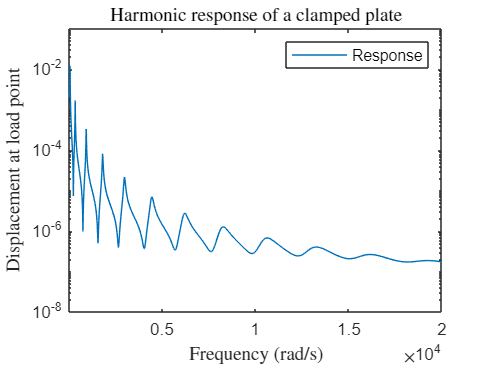

clear; close all;

% nx = 80;        % elements in x
% ny = 16;        % elements in y
% l = 0.3;        % length
% w = 0.025;      % width
% h = 0.002;      % height
% 
% [model, x0, xend] = createRectangularPlate(l,w,nx,ny,...
%     'elementType','ReissnerMindlinElement3d4n');
% model.getAllNodes.addDof({'DISPLACEMENT_Z', 'ROTATION_X', 'ROTATION_Y'});
% 
% x0.fixAllDofs();        % clamped at x=0.0
% xend.fixAllDofs();      % clamped at x=0.3
% 
% id_load = fix(length(model.getAllNodes())/2)+1;
% model.getNode(id_load).setDofLoad('DISPLACEMENT_Z',1);
% 
% model.getAllElements.setPropertyValue('YOUNGS_MODULUS',2.1e11);
% model.getAllElements.setPropertyValue('POISSON_RATIO',.3);
% model.getAllElements.setPropertyValue('THICKNESS',h);
% model.getAllElements.setPropertyValue('DENSITY',7860);
% model.getAllElements.setPropertyValue('NUMBER_GAUSS_POINT',2);
% model.getAllElements.setPropertyValue('SHEAR_CORRECTION_FACTOR',5/6);
% model.getAllElements.setPropertyValue('RAYLEIGH_ALPHA',0.01);
% model.getAllElements.setPropertyValue('RAYLEIGH_BETA',1e-6);
% 
% [~,K] = SimpleAssembler.assembleGlobalStiffnessMatrix(model);
% [~,C] = SimpleAssembler.assembleGlobalDampingMatrix(model);
% [~,M] = SimpleAssembler.assembleGlobalMassMatrix(model);
% [~,f] = SimpleAssembler.applyExternalForces(model);

[M, C, K, f, ~] = fem_beam(1,100);

o = sparse(1,length(f));
o(f~=0) = 1; %This allows us to get the displacement for the corresponding DOF at the tip

s = 1i*logspace(0,log10(2e4),1000);
result_full = zeros(1,length(s));

tic
for ii=1:length(s)
    result_full(ii) = o * ((s(ii)^2*M + s(ii)*C + K) \ f);
end
ctime_full = toc;

fig = figure('Name','Frequency response');
set(fig,'defaulttextinterpreter','latex')
semilogy(abs(s),abs(result_full))
xlim([10 2e4])
ylim([1e-8 1e-1])
legend('Response')
title('Harmonic response of a clamped plate')
ylabel('Displacement at load point')
xlabel('Frequency (rad/s)')

We now project the system onto a low dimensional Krylov subspace, which, contains our desired solution. We choose the second approach and build the subspace around some expansion points $s_{0,i}$ distributed in the frequency range of interest.

s0 = 1i*linspace(500,2e4,5);
V = zeros(length(f),length(s0));

for ii=1:length(s0)
    V(:,ii) = (s0(ii)^2*M + s0(ii)*C + K) \ f;
end

[V,~] = qr(V,0);    %orthogonalization


Now, we project the full system onto the reduced space by


$$K_r = V^T K V,\quad C_r = V^T C V,\quad M_r = V^T M V,\quad f_r=V^T f$$


and solve the reduced system.

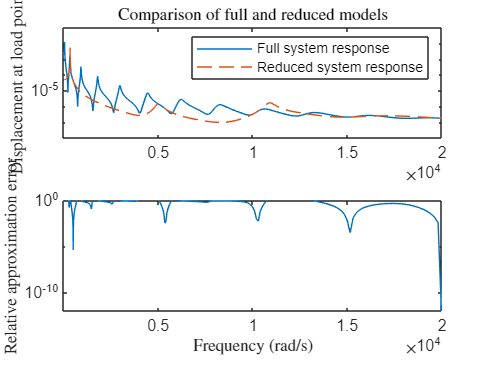

tic
Kr = V.' * K * V;
Cr = V.' * C * V;
Mr = V.' * M * V;
fr = V.' * f;
or = o * V;

result_krylov = zeros(1,length(s));
for ii=1:length(s)
    result_krylov(ii) = or * ((s(ii)^2*Mr + s(ii)*Cr + Kr) \ fr);
end
ctime_krylov = toc;
speedup = ctime_full/ctime_krylov;
error = (result_full - result_krylov)./result_full;
error_norm = norm((result_full - result_krylov)./result_full);

fig = figure('Name','Frequency response');
set(fig,'defaulttextinterpreter','latex')
subplot(2,1,1)
semilogy(abs(s),abs(result_full),abs(s),abs(result_krylov),'--')
xlim([10 2e4])
ylim([1e-8 1e-1])
legend('Full system response', 'Reduced system response')
title('Comparison of full and reduced models')
ylabel('Displacement at load point')
subplot(2,1,2)
semilogy(abs(s),abs(error))
xlim([1 2e4])
ylim([1e-12 1])
ylabel('Relative approximation error')
xlabel('Frequency (rad/s)')


fprintf("Computation time for a full system solve: %.3f s\n" + ...
    "Computation time for the reduced system: %.3f s\n" + ...
    "Resulting speedup of the reduction process: %.2f\n\n" + ...
    "Norm of relative approximation error: %e\n", ...
    ctime_full, ctime_krylov, speedup, error_norm);

Computation time for a full system solve: 15.515 s
Computation time for the reduced system: 0.031 s
Resulting speedup of the reduction process: 502.88

Norm of relative approximation error: 5.009753e+01


Again, the choice of expansion points has a large influence on the quality of the solution. As an example, we choose expansion points which are not suited to approximate the system.

s0 = 1i*[3000 6000 12000 13000 14000];
V = zeros(length(f),length(s0));

for ii=1:length(s0)
    V(:,ii) = (s0(ii)^2*M + s0(ii)*C + K) \ f;
end

[V,~] = qr(V,0);    %orthogonalization

Kr = V.' * K * V;
Cr = V.' * C * V;
Mr = V.' * M * V;
fr = V.' * f;
or = o * V;

result_krylov_2 = zeros(1,length(s));
for ii=1:length(s)
    result_krylov_2(ii) = or * ((s(ii)^2*Mr + s(ii)*Cr + Kr) \ fr);
end
ctime_krylov = toc;
speedup = ctime_full/ctime_krylov;
error_2 = (result_full - result_krylov_2)./result_full;
error_norm_2 = norm((result_full - result_krylov_2)./result_full);

fprintf("Norm of relative approximation error (model 1): %e\n" + ...
    "Norm of relative approximation error (model 2): %e\n", ...
    error_norm, error_norm_2);

Norm of relative approximation error (model 1): 5.009753e+01
Norm of relative approximation error (model 2): 3.758268e+01


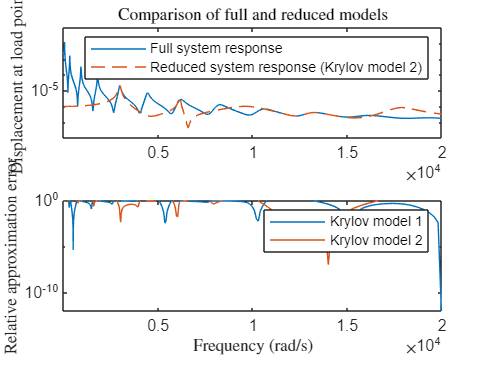


fig = figure('Name','Frequency response');
set(fig,'defaulttextinterpreter','latex')
subplot(2,1,1)
semilogy(abs(s),abs(result_full),abs(s),abs(result_krylov_2),'--')
xlim([10 2e4])
ylim([1e-8 1e-1])
legend('Full system response', ...
    'Reduced system response (Krylov model 2)')
title('Comparison of full and reduced models')
ylabel('Displacement at load point')
subplot(2,1,2)
semilogy(abs(s),abs(error),abs(s),abs(error_2))
xlim([1 2e4])
ylim([1e-12 1])
legend('Krylov model 1', 'Krylov model 2')
ylabel('Relative approximation error')
xlabel('Frequency (rad/s)')

The approximation quality is much lower than in the run before. Therefore, iterative methods have been introduced to find good expansion points, even if the response of the full system might not be known in advance.

Such an extenstion to the framework presented above is the Iterative Rational Krylov Algorithm (IRKA), which finds a to some extent optimal reduced model for a given reduced order iteratively. Between iterations, the expansion points are updated using the mirror images of the eigenvalues of the current reduced system:

- Compute $V$ using an initial set of expansion points $s_i$

- Reduce the system

- Solve the quadratic eigenvalue problem, which yields $2r$ eigenvalues

- Choose $r
$ eigenvalues $\lambda_r$ and update the expansion points $s_i=-\lambda_r$, usually take smalles eigenvalues and complex conjugate ones %Matlab allows you to choose that

- Check convergence

In step 4, any of the eigenvalues can be chosen. It is therefore possible to adaptively find a reduced model, which is valid in a specific frequency region.

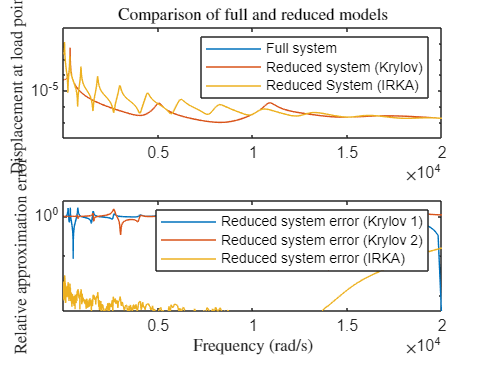

s0 = 1i*linspace(500,2e4,20);

tic

tol = 1e-10;
maxiter = 10;

%[Mr, Cr, Kr, fr, or, sr] = irka(M, C, K, f, o, s0, tol, maxiter);

r = length(s0);
s0_old = s0;

% compute the initial reduction basis
V = zeros(length(f),length(s0));
for ii=1:length(s0)
    V(:,ii) = (s0(ii)^2*M + s0(ii)*C + K) \ f;
end
[V, ~] = qr(V,0);

% start IRKA loop
iter = 1;
err = 1;
while (iter < 10) && (err > 1e-10)
    Mr = V' * M * V;
    Cr = V' * C * V;
    Kr = V' * K * V;
    
    lam = sort(polyeig(Kr,Cr,Mr));
    s0 = -lam(1:r);
    
    err = norm(sort(abs(s0)) - sort(abs(s0_old)))/norm(s0_old);
    iter = iter + 1;
    s0_old = s0;
    
    for ii=1:length(s0)
        V(:,ii) = (s0(ii)^2*M + s0(ii)*C + K) \ f;
    end
    [V, ~] = qr(V,0); 
end

% project the system
Mr = V' * M * V;
Cr = V' * C * V;
Kr = V' * K * V;
fr = V' * f;
or = o * V;

ctime_irka = toc;

% compute the reduced system's response
result_irka = zeros(1,length(s));
for ii=1:length(s)
    result_irka(ii) = or * ((s(ii)^2*Mr + s(ii)*Cr + Kr) \ fr);
end

error_irka = (result_full - result_irka)./result_full;
error_norm_irka = norm(result_full - result_irka)/norm(result_full);

fig = figure();
set(fig,'defaulttextinterpreter','latex')
subplot(2,1,1)
semilogy(abs(s),abs(result_full),abs(s),abs(result_krylov),...
    abs(s),abs(result_irka))
xlim([10 2e4])
ylim([1e-8 1e-1])
legend('Full system', 'Reduced system (Krylov)', 'Reduced System (IRKA)')
title('Comparison of full and reduced models')
ylabel('Displacement at load point')
subplot(2,1,2)
semilogy(abs(s),abs(error),abs(s),abs(error_2),abs(s),abs(error_irka))
xlim([1 2e4])
ylim([1e-12 100])
legend('Reduced system error (Krylov 1)', ...
    'Reduced system error (Krylov 2)', ...
    'Reduced system error (IRKA)',...
    'Location','northeast')
ylabel('Relative approximation error')
xlabel('Frequency (rad/s)')


fprintf("Error norm for Krylov model 1: %.3e\n" + ...
    "Error norm for Krylov model 2: %.3e\n" + ...
    "Error norm for IRKA: %.3e\n", ...
    error_norm, error_norm_2, error_norm_irka);

Error norm for Krylov model 1: 5.010e+01
Error norm for Krylov model 2: 3.758e+01
Error norm for IRKA: 1.100e-08


Try experimenting with different initial values for IRKA and the desired reduced order. Also try what happens, if not the eigenvalues with the lowest absolute value are chosen as expansion points in the next iteration, but some other values.